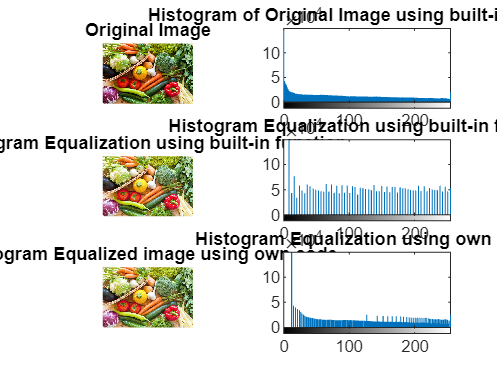

clc;
clear all;
close all;

original_image = imread('photo1.jpeg');

subplot(3,2,1);
imshow(original_image);
title('Original Image');

subplot(3,2,2);
imhist(original_image);
title('Histogram of Original Image using built-in function');
axis tight;

histogram_bins = zeros(1, 256);
[image_rows, image_cols] = size(original_image);
total_pixels = image_rows * image_cols;
intensity_range = 0:255;

histogram_equalized_image = histeq(original_image);

subplot(3,2,3);
imshow(histogram_equalized_image);
title('Histogram Equalization using built-in function');

subplot(3,2,4);
imhist(histogram_equalized_image);
axis tight;
title('Histogram Equalization using built-in function');

% Calculating Histogram without built-in function
for i = 1:image_rows
    for j = 1:image_cols
        histogram_bins(original_image(i,j) + 1) = histogram_bins(original_image(i,j) + 1) + 1;
    end
end

% Calculating Probability
for i = 1:256
    histogram_bins(i) = histogram_bins(i) / total_pixels;
end

% Calculating Cumulative Probability
cumulative_prob = histogram_bins(1);
for i = 2:256
    cumulative_prob = cumulative_prob + histogram_bins(i);
    histogram_bins(i) = cumulative_prob;
end

% Mapping
for i = 1:image_rows
    for j = 1:image_cols
        original_image(i,j) = round(histogram_bins(original_image(i,j) + 1) * 255);
    end
end

subplot(3,2,5);
imshow(original_image);
title('Histogram Equalized image using own code');

subplot(3,2,6);
imhist(original_image);
axis tight;
title('Histogram Equalization using own code');